## **Question-6**

**Step-a: **Load the x.mat and sound the input signal.

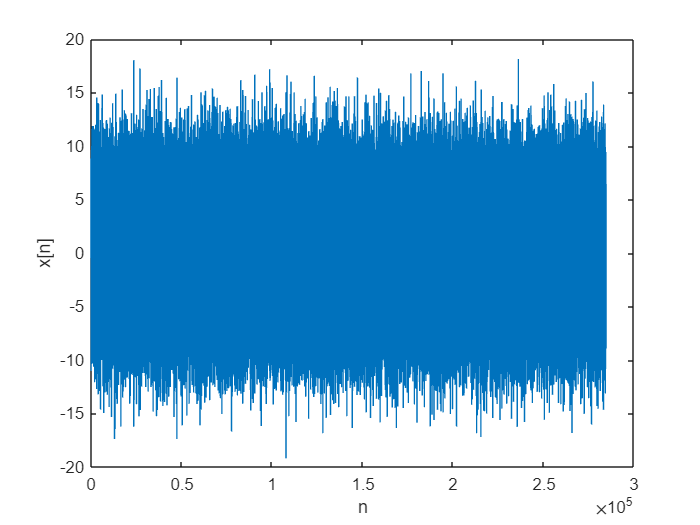

close all;
clear;
load('x.mat');


N = length(x);
sound(x,44100);

figure; plot(x);
xlabel('n');
ylabel('x[n]');

By listening the x signal, it can be said that the original clean sound cannot be determined by just hearing this noisy sound.

**Step-b: **Apply the Fourier Tranform commands and plot the input signal's FT.

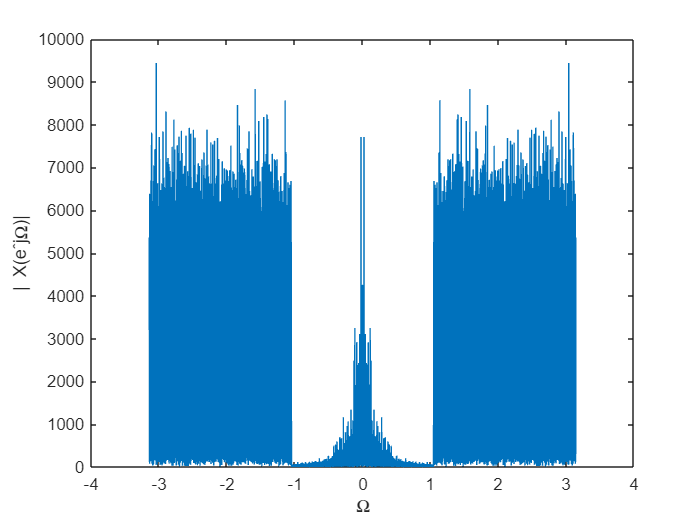

X=fftshift(fft(x));
Omega=linspace(-pi,pi,N+1);
Omega=Omega(2:end);

figure; plot(Omega,abs(X));
xlabel('\Omega');
ylabel('| X(eˆ{j\Omega})|');

We know from the informtion given in the question, noise component of the signal has a strong magnitude and a flat spectrum that covers  high-frequencies. Also, that means the clean sound has lower frequencies. It can be seen from the plot that there is a certain change both in Omega = 1 & -1. These 1 & -1 points have lower frequencies compared in one period which lead us to take B=1.

Real & Imaginary Part plotting:

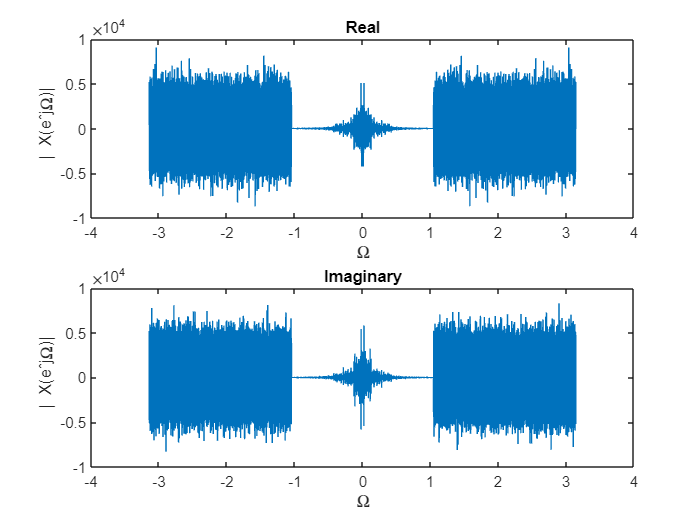

figure; 
subplot(2,1,1)
plot(Omega,real(X));
xlabel('\Omega'); ylabel(' | X(eˆ{j\Omega})|');
title('Real');

subplot(2,1,2);
plot(Omega,imag(X));
xlabel('\Omega'); ylabel(' | X(eˆ{j\Omega})|'); 
title('Imaginary');

**Step-c:** Obtain the low-pass filter.

H = zeros(1,N);
B = 1;
index1 = find(Omega >-(B-1e-6),1);
index2 = find(Omega > (B-1e-6),1);
H(index1:index2) = 1;

In this part H(exp(j*omega)) works as a low-pass filter. So, by selecting |B|=1 we will obtain the above function.

**Step-d:** Determine Y(exp(j*omega)) by convolution property Y(exp(j*omega)) = H(exp(j*omega))*X(exp(j*omega));

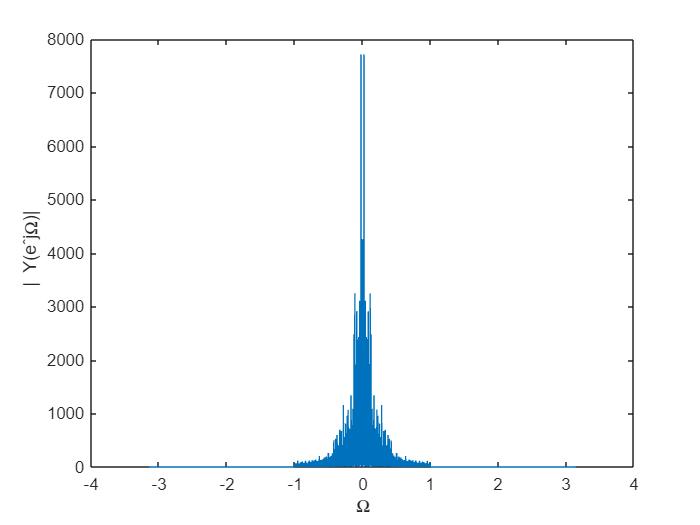

Y=H.*X;
figure; plot(Omega,abs(Y));
xlabel('\Omega');
ylabel(' | Y(eˆ{j\Omega})|');

As asked in the question, we assigned different B values to obtain different output signals as well.

H_different = zeros(3,N);
B_different = [0.25 , 1.7 , 2.5];
for i=1:3
    
    index1_D(i) = find(Omega >-B_different(i),1);
    index2_D(i) = find(Omega > B_different(i),1);

    H_different(i,index1_D(i):index2_D(i)) = 1;    
    Y_different(i,:) = H_different(i,:) .* X;

end

Plot of the output signals' Fourier Transforms is given below.

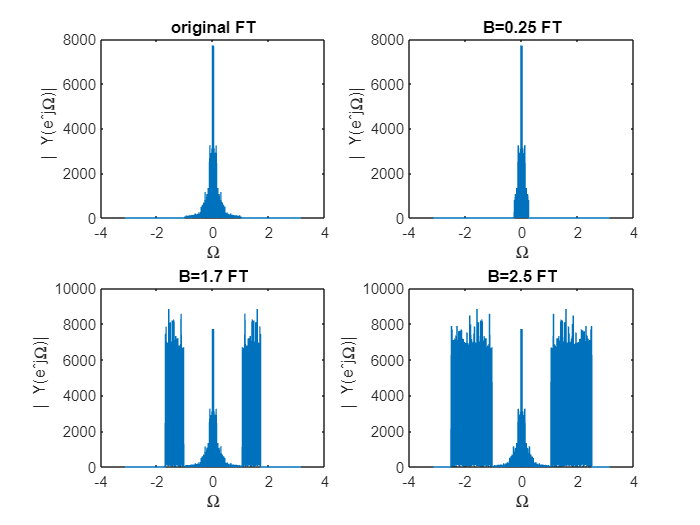

figure;
subplot(2,2,1);
plot(Omega,abs(Y));
xlabel('\Omega');
ylabel(' | Y(eˆ{j\Omega})|'); title('original FT');

subplot(2,2,2);
plot(Omega,abs(Y_different(1,:)));
xlabel('\Omega');
ylabel(' | Y(eˆ{j\Omega})|'); title('B=0.25 FT');

subplot(2,2,3);
plot(Omega,abs(Y_different(2,:)));
xlabel('\Omega');
ylabel(' | Y(eˆ{j\Omega})|'); title('B=1.7 FT');

subplot(2,2,4);
plot(Omega,abs(Y_different(3,:)));
xlabel('\Omega');
ylabel(' | Y(eˆ{j\Omega})|'); title('B=2.5 FT');

**Part-e:** Calculate the output signal by using its fourier transform.

y=ifft(ifftshift(Y));

y_different(1,:) = ifft(ifftshift(Y_different(1,:)));
y_different(2,:) = ifft(ifftshift(Y_different(2,:)));
y_different(3,:) = ifft(ifftshift(Y_different(3,:)));

Output signal vs Input signal plot is given below as well.

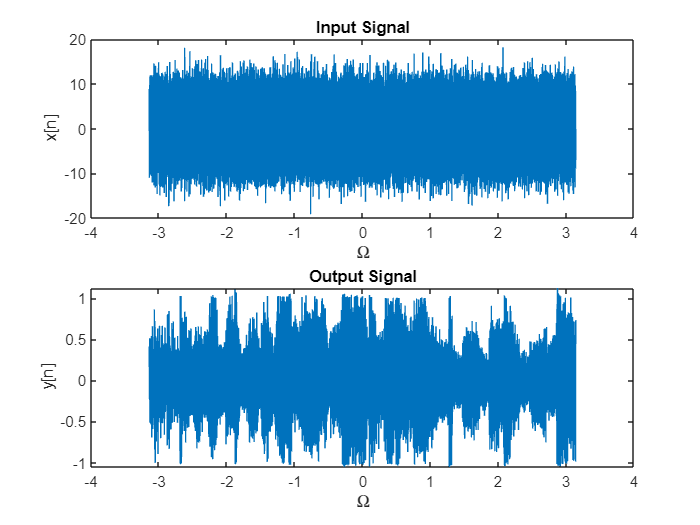

figure;
subplot(2,1,1);
plot(Omega,x);
xlabel('\Omega');
ylabel('x[n]'); title('Input Signal');

subplot(2,1,2);
plot(Omega,real(y));
xlabel('\Omega');
ylabel('y[n]'); title('Output Signal');

**Part-f:** Listening part.

sound(real(y),44100);

Obviously, the song is "Hotel California" :)

Since we can clearly hear the song hidden in the noisy signal, it is possible to say that we have selected the correct B value.

In the below block, there are sounds for the different B values.

sound(real(y_different(1,:)),44100);
sound(real(y_different(2,:)),44100);
sound(real(y_different(3,:)),44100);

For the lower frequency than B has still clear sound, it can be easily understandible. However, there is a problem with the quality of the sound, the noise might be gone but there is still a corruption in the signal.

And for the higher frequency values, it becomes harder to understand by drifting apart the exact B value. 